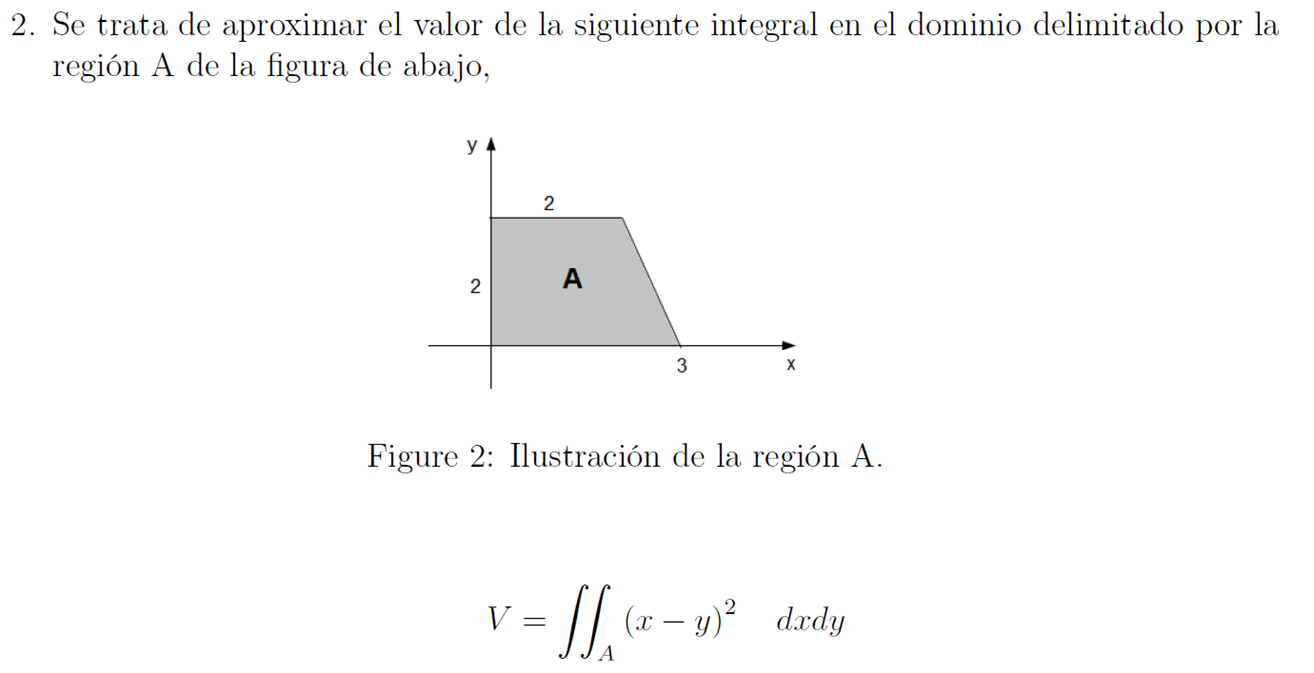

La ecuación que pasa por los puntos $P=\left(x_1 =2,y_1 =2\right)$ y $Q=\left(x_2 =3,y_2 =0\right)$ se puede calcular como:

$y=m\;x+\left(y_1 -{\mathrm{mx}}_1 \right)$, donde $m=\frac{\left(y_2 -y_1 \right)}{\left(x_2 -x_1 \right)}=\frac{\left(0-2\right)}{3-2}=-2$, Entones, $y=-2x+6$

## Solución Numérica en Matlab


close all
clear all


% definir el dominio de integración
a=0; b=3;    % a< x <b
c=0; d=2;    % c< y <d

% Declarar las variables simbólicas
syms x y

% Definir la función
f = (x - y)^2;

% Definir los límites de integración
x_min = a;
x_max = 3 - y/2; % Límite superior de x depende de y
y_min = c;
y_max = d;

% Calcular la integral doble
result = double(int(int(f, x, x_min, x_max), y, y_min, y_max))

result =    5.833333333333333



close all
clear all


% definir el dominio de integración
a=0; b=3;    % a< x <b
c=0; d=2;    % c< y <d

% definir la superficie
f=@(x,y) (x-y).^2;

% Iniciar el experimento de Monte Carlo
nc=0;               % aciertos
n=50000;             % numero de intentos

% generar n números aleatorios uniformes entre 0 y 1 
r=rand(n,3);

% generamos una nube de n puntos en R [a,b]x[c,d]xh
% los puntos siguen una distribución uniforme en los intervalos
% [a,b], [c,d] y [0,h], donde h es una cota superior de f
x=a+r(:,1)*(b-a);         y=c+r(:,2)*(d-c);         
h = max(f(x,y));
z=r(:,3)*h;


% Definimos el volumen del hiperpoliedro R
R = (b-a)*(d-c)*h;

% localizar los puntos que se encuentran debajo de la superficie f
idx=z<=f(x,y) & y<=(-2*x+6);
%--------------Contar el número de éxitos
nc=sum(idx);
vol_esti=R*nc/n

vol_esti =    5.857172441690122


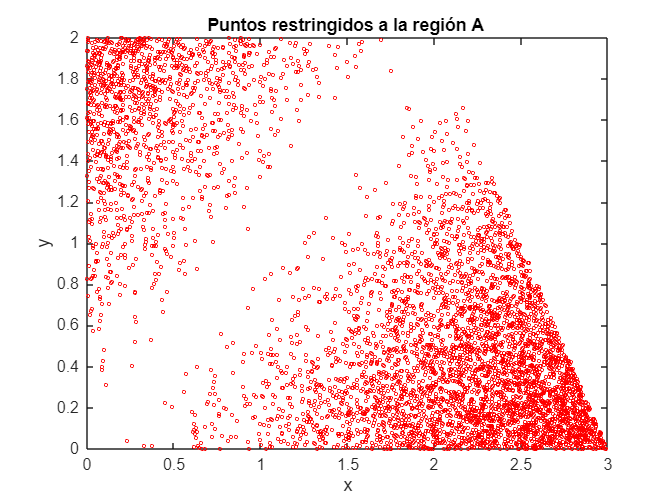



%--------------Dibujar los resultados
figure;
plot(x(idx,1),y(idx,1),'ro','MarkerSize',2);
xlabel('x');ylabel('y');title('Puntos restringidos a la región A ')

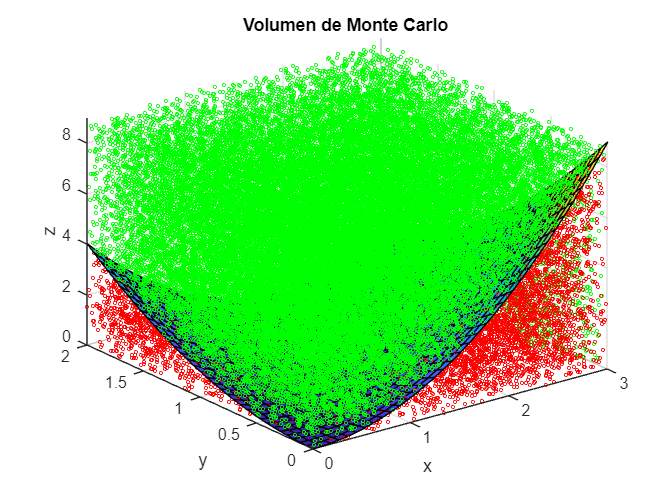

%plot(x(~idx,1),y(~idx,1),'-go')

figure;
fsurf(f,[a b c d]);
hold on
plot3(x(idx,1),y(idx,1),z(idx,1),'ro','MarkerSize',2) % Puntos que satisfacen el criterio
plot3(x(~idx,1),y(~idx,1),z(~idx,1),'go','MarkerSize',2) % Puntos que no satisfacen el criterio
xlabel('x');ylabel('y');zlabel('z'); title('Volumen de Monte Carlo ')